clc
clearvars
close all

simulation = load("Kokam_ref2022\CELL_LauraKokam_parameters15y_modelV18_15z2_22032020_v2.mat").Simulation;
sim_res = struct2table(simulation.Galvanostatic);
real = load("Kokam_ref2022\test_info_fin_26032021.mat").test_info;

c_rates = [0.1 0.2 0.5 1 2 -0.1 -0.2 -0.5 -1 -2]; %Empezamos con C rates positivas
temps = [5 25 45] + 273.15;

C rate: 0.10

T: 5.00

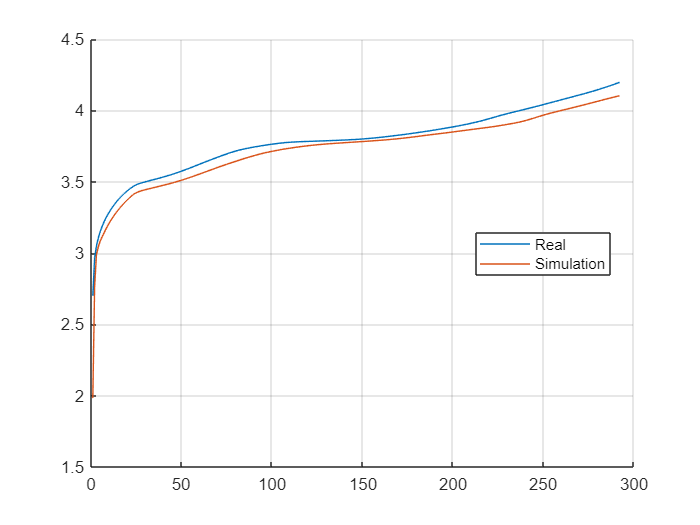

C rate: 0.10

T: 25.00

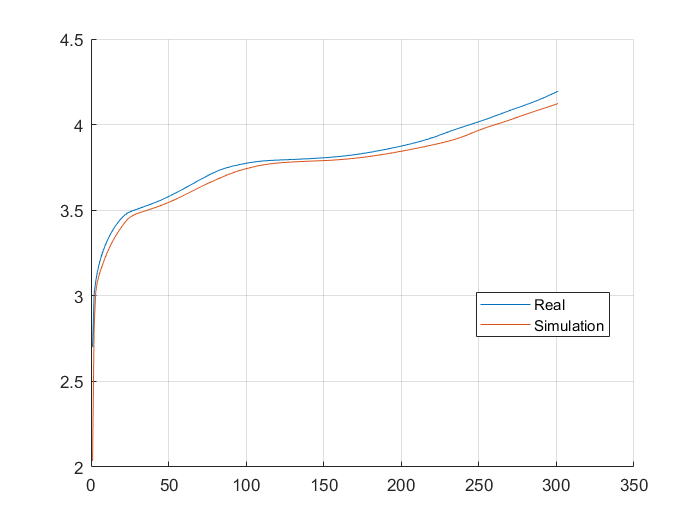

C rate: 0.10

T: 45.00

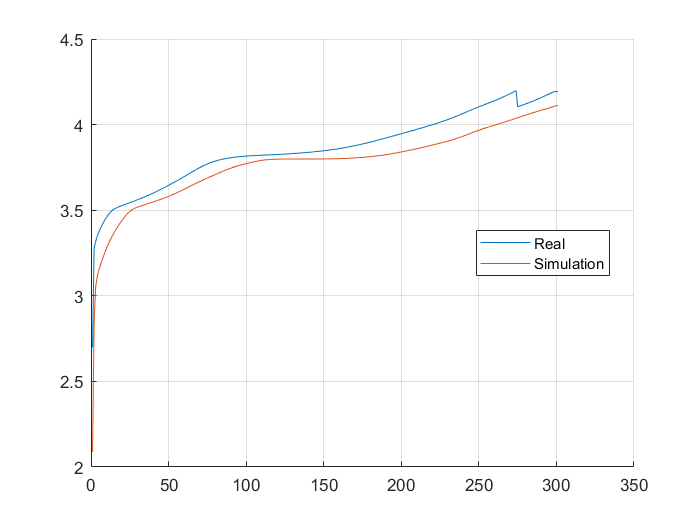

C rate: 0.20

T: 5.00

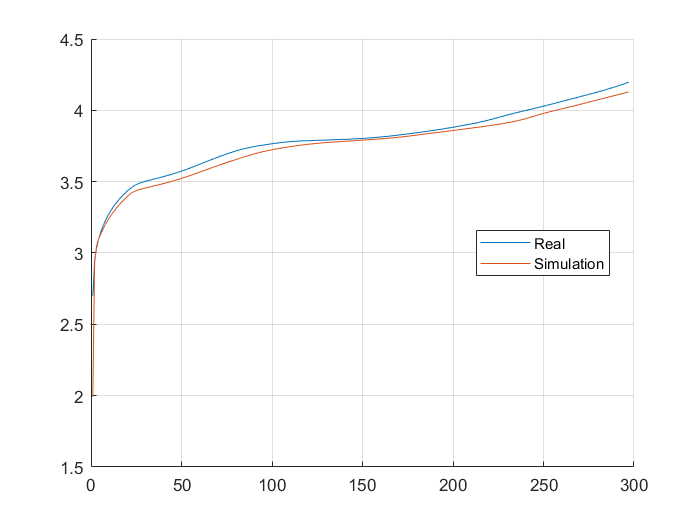

C rate: 0.20

T: 25.00

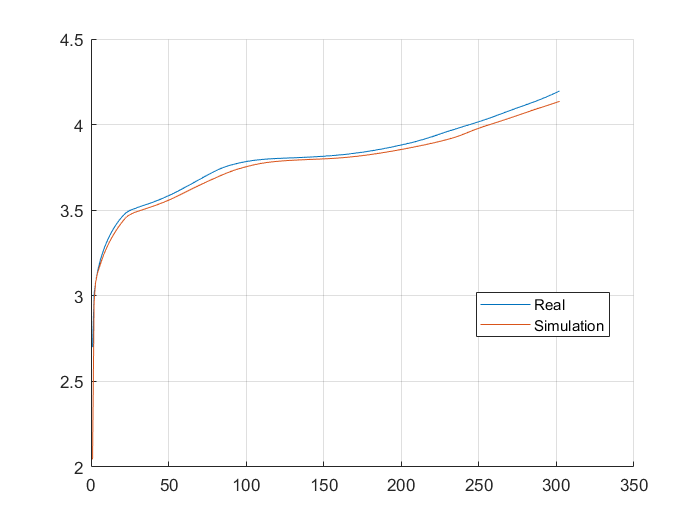

C rate: 0.20

T: 45.00

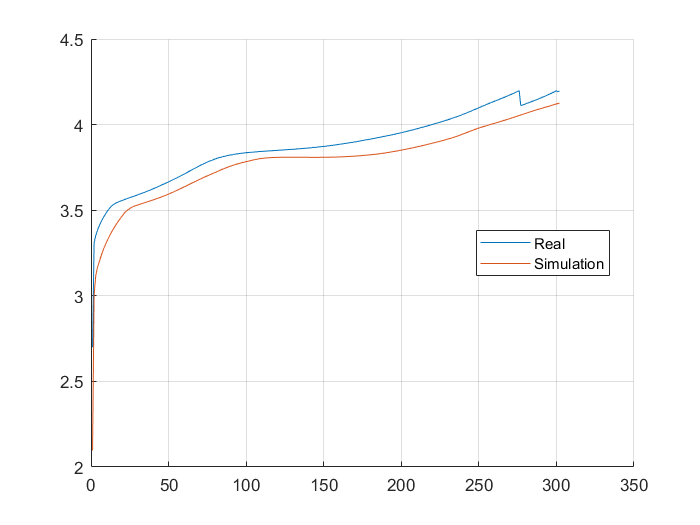

C rate: 0.50

T: 5.00

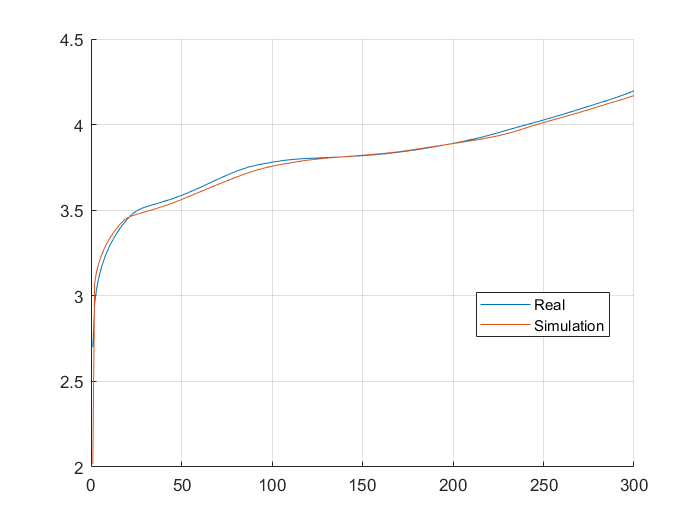

C rate: 0.50

T: 25.00

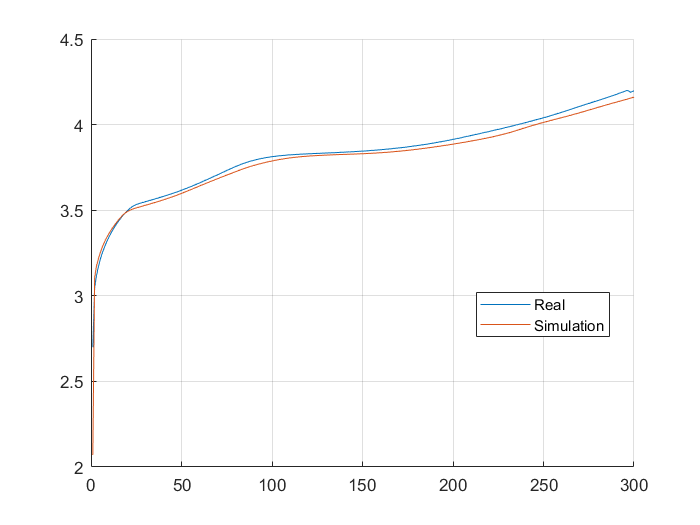

C rate: 0.50

T: 45.00

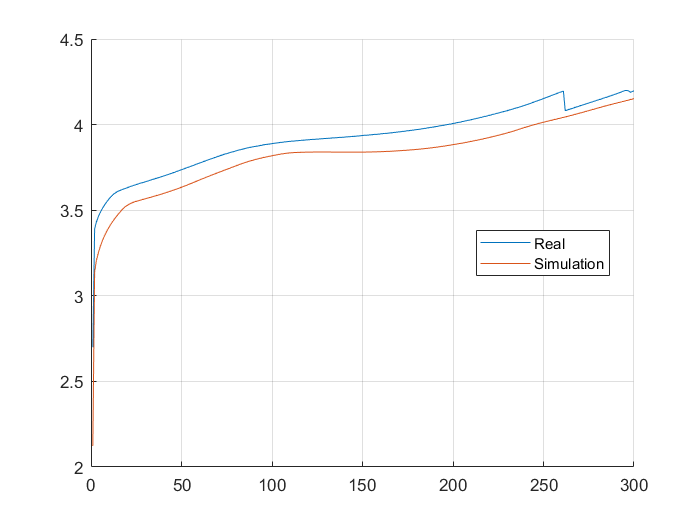

C rate: 1.00

T: 5.00

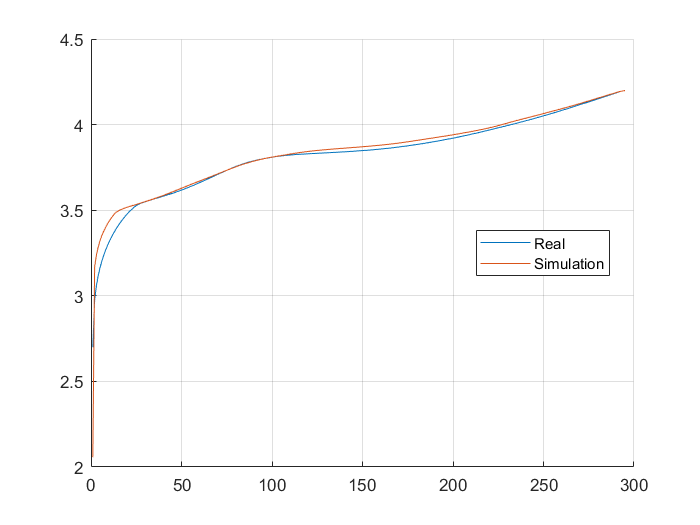

C rate: 1.00

T: 25.00

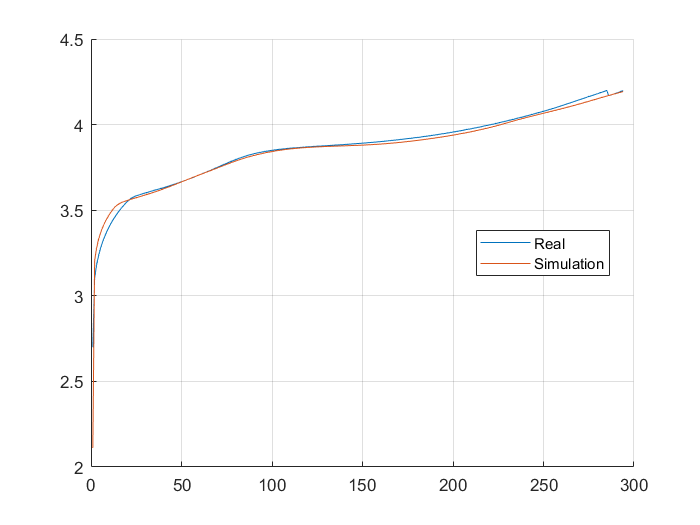

C rate: 1.00

T: 45.00

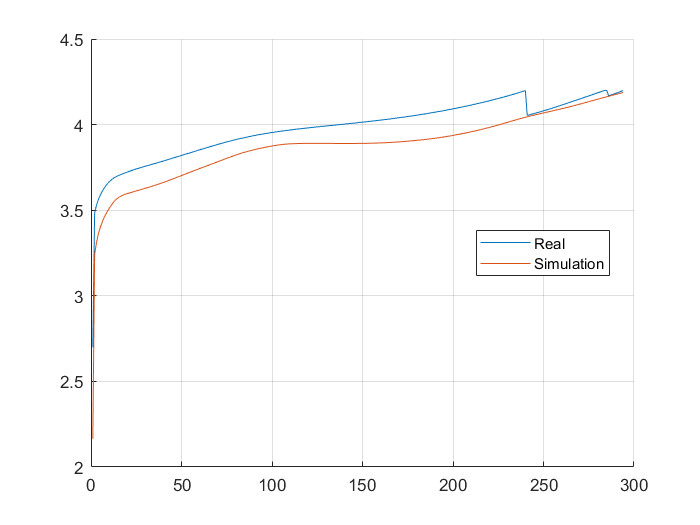

C rate: 2.00

T: 5.00

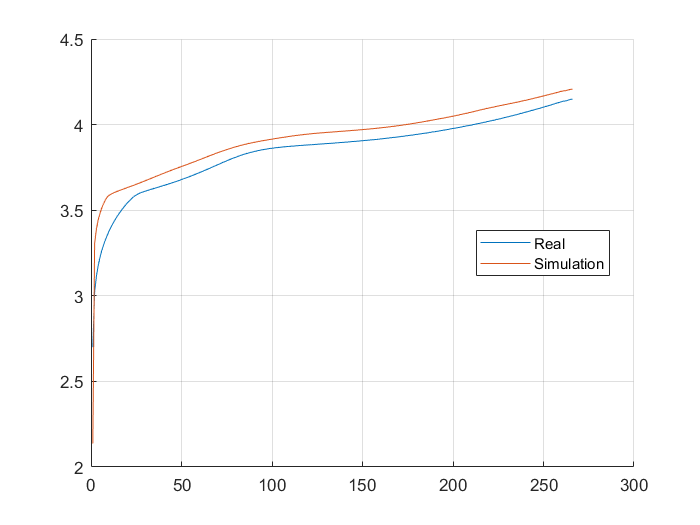

C rate: 2.00

T: 25.00

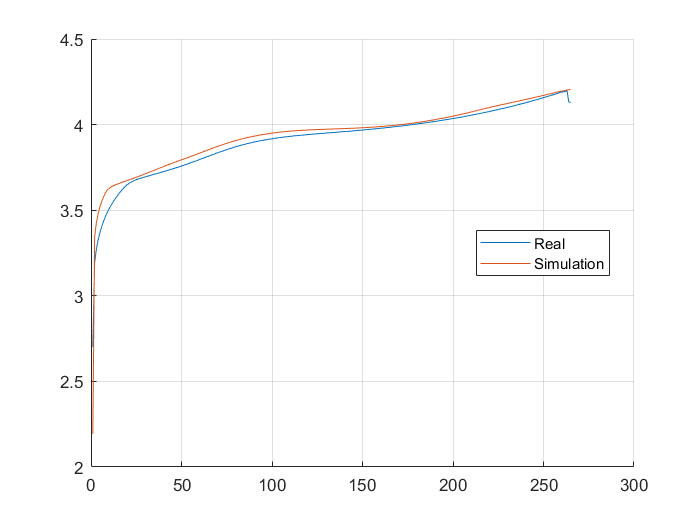

C rate: 2.00

T: 45.00

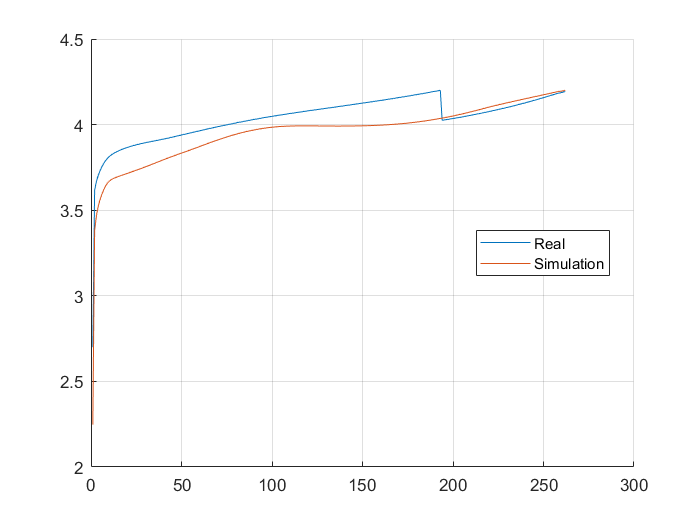

C rate: -0.10

T: 5.00

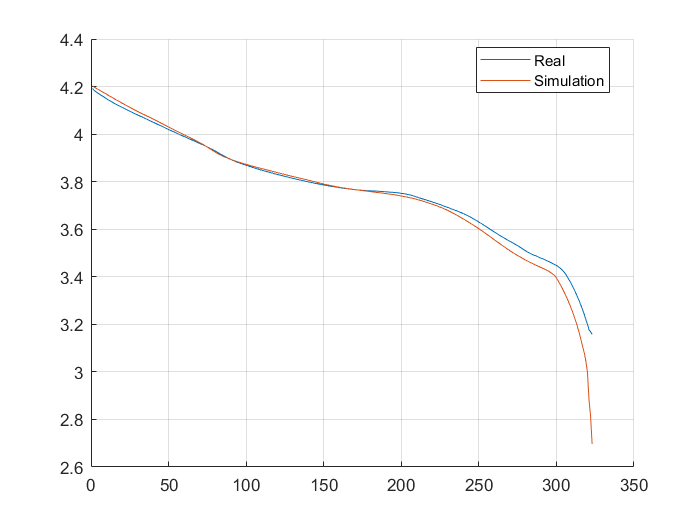

C rate: -0.10

T: 25.00

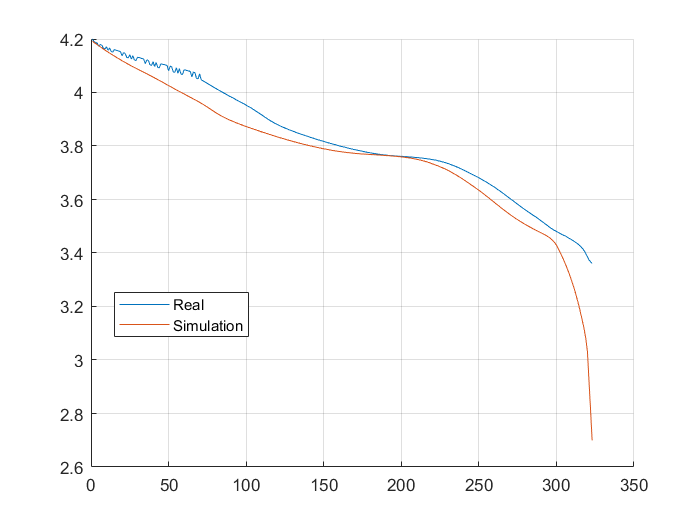

C rate: -0.10

T: 45.00

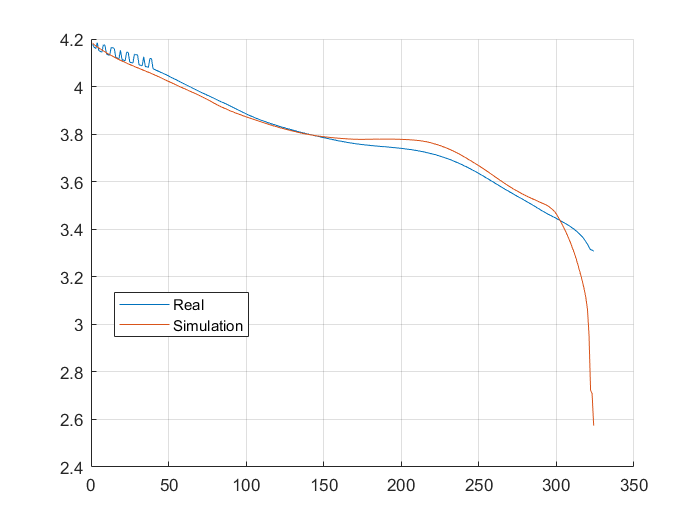

C rate: -0.20

T: 5.00

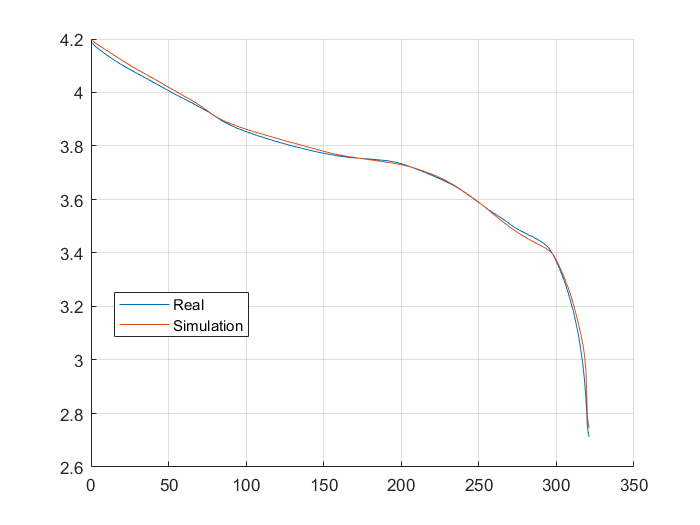

C rate: -0.20

T: 25.00

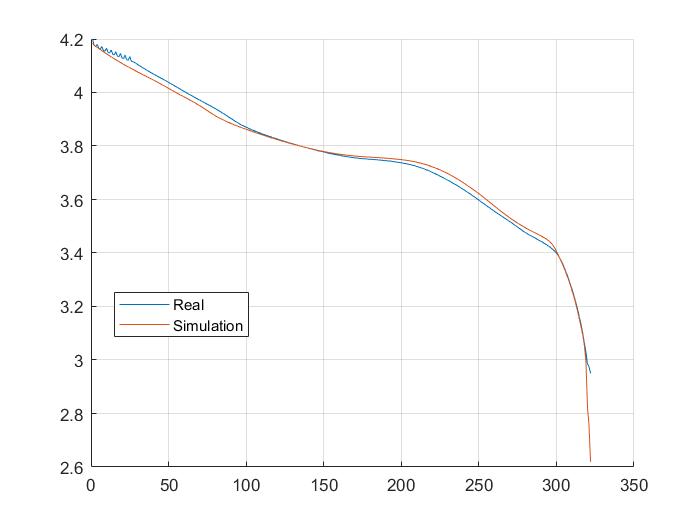

C rate: -0.20

T: 45.00

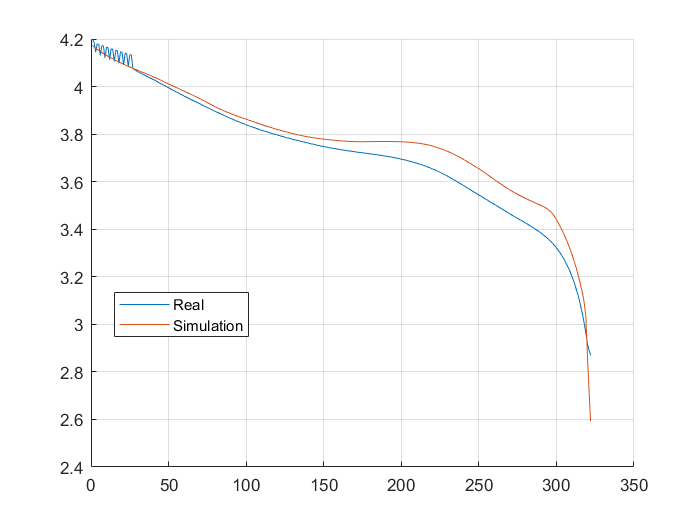

C rate: -0.50

T: 5.00

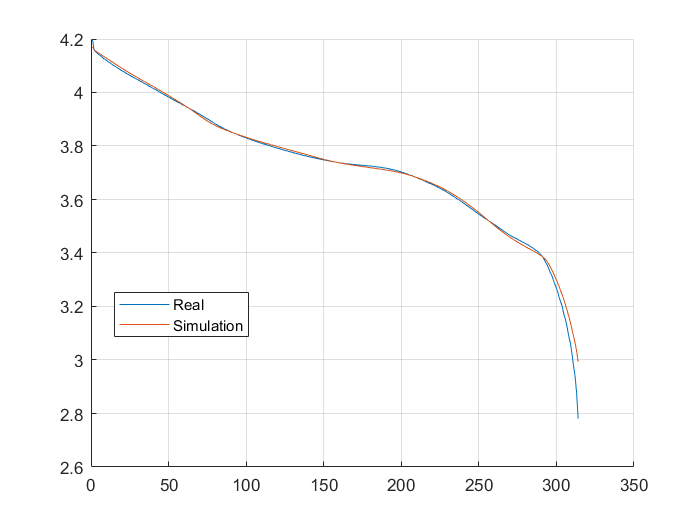

C rate: -0.50

T: 25.00

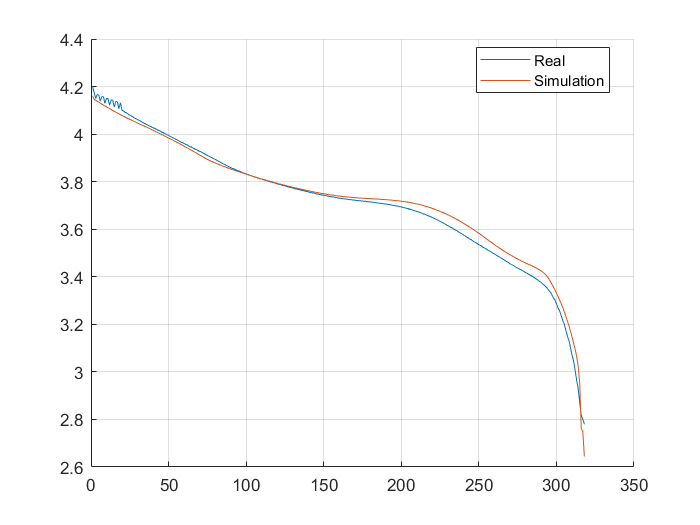

C rate: -0.50

T: 45.00

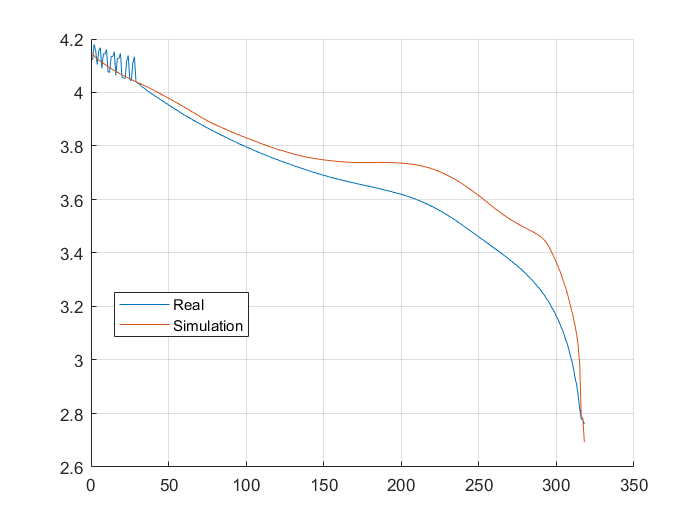

C rate: -1.00

T: 5.00

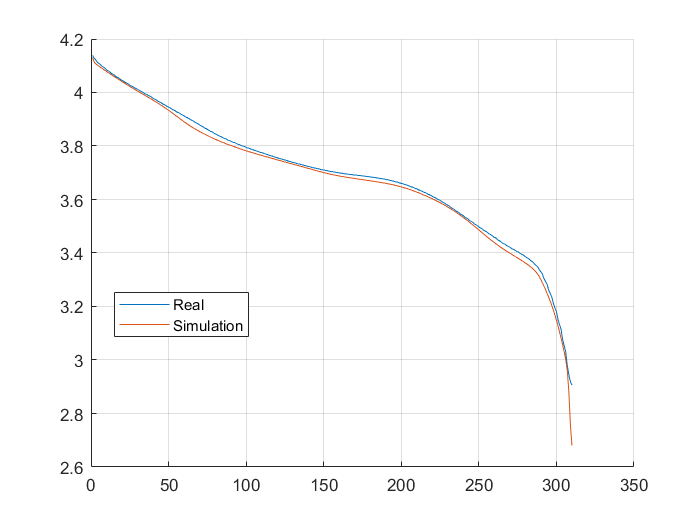

C rate: -1.00

T: 25.00

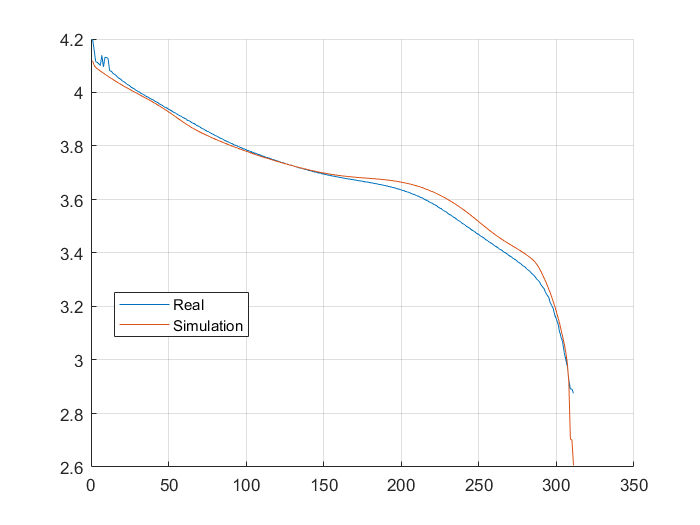

C rate: -1.00

T: 45.00

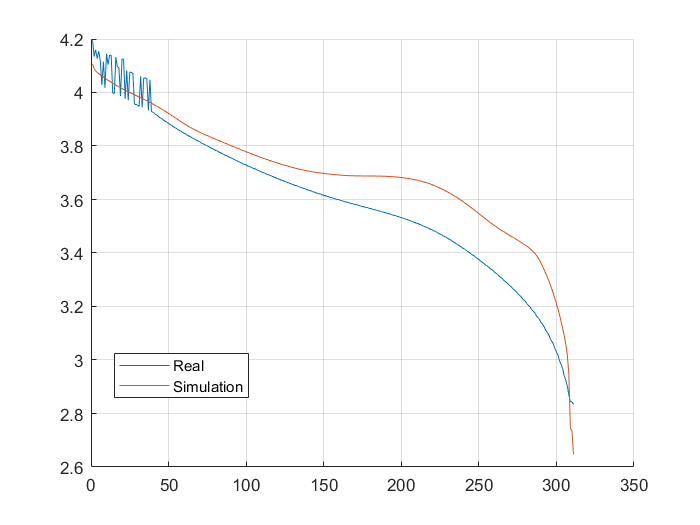

C rate: -2.00

T: 5.00

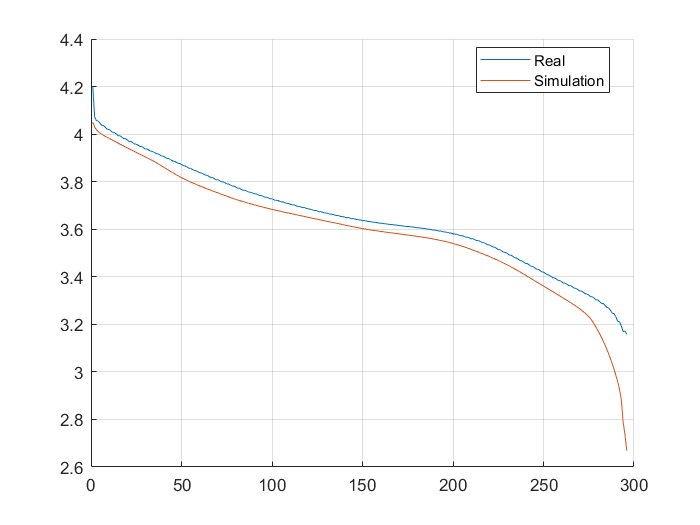

C rate: -2.00

T: 25.00

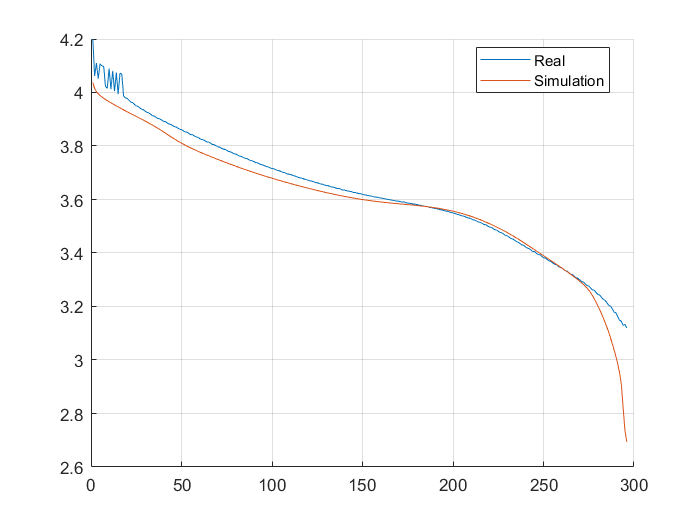

C rate: -2.00

T: 45.00

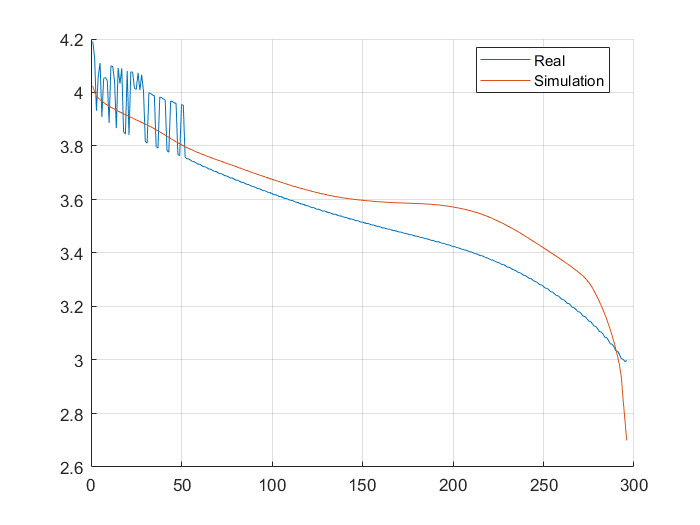

Data = [];
for c_i = 1:length(c_rates)
    for temp_i = 1:length(temps)
        tab = sim_res(sim_res.Crate == c_rates(c_i) & sim_res.T0 == temps(temp_i), :);

        target = struct2table(real(temp_i*2 - 1).test.For_sim.Crate);
        target = target(target.Crate == c_rates(c_i), :);
        [~, idx] = sort(cell2mat(target.time));

        SOC_real = cell2mat(target.voltage);
        SOC_real = SOC_real(idx);
        timestamps = floor(tab.time.d1+1);
%         fprintf("%d %d",timestamps(end), length(E_real))
        timestamps_idx = timestamps <= (length(SOC_real) + 1);
        timestamps = timestamps(timestamps_idx);

        SOC_real = SOC_real(timestamps);
        SOC_sim = cell2mat(tab.Ecell);
        SOC_sim = SOC_sim(1:length(timestamps));

        fprintf("C rate: %.2f",c_rates(c_i))
        fprintf("T: %.2f",temps(temp_i) - 273.15)
        figure
        hold on
        grid on
        plot(SOC_real)
        plot(SOC_sim)
        legend(["Real", "Simulation"], "Location","best")
        frame = [];
        names = [];

        % Phis
        indexes = [18, 30];
        indexes = [1:18, 30:43];
        for k = 1:length(indexes)
            names = [names "phis_"+num2str(indexes(k))];
            frame = [frame tab.phis.d1(timestamps_idx, indexes(k))];
        end

        % Phil
        indexes = [1, 18, 30, 41];
        indexes = 1:41;
        for k = 1:length(indexes)
            names = [names "phil_"+num2str(indexes(k))];
            frame = [frame tab.phil.d1(timestamps_idx, indexes(k))];
        end

        % cl
        indexes = [1, 18, 30, 41];
        indexes = 1:41;
        for k = 1:length(indexes)
            names = [names "cl_"+num2str(indexes(k))];
            frame = [frame tab.cl.d1(timestamps_idx, indexes(k))];
        end

        % cs_surf
        indexes = [1, 18, 30, 43];
        indexes = [1:18, 30:43];
        for k = 1:length(indexes)
            names = [names "cs_surface_"+num2str(indexes(k))];
            frame = [frame tab.cs_surface.d1(timestamps_idx, indexes(k))];
        end

        % T
        indexes = [1, 18, 30, 41];
        indexes = 1:41;
        for k = 1:length(indexes)
            names = [names "T_"+num2str(indexes(k))];
            frame = [frame tab.T.d1(timestamps_idx, indexes(k))];
        end
        
        % 1D variables
        vars_1D = {'Ecell' 'Epos' 'Eneg' 'capa' 'enerden' 'Qtot' 'poden'...
            'R0_estim' 'SOCneg_ave' 'SOCpos_ave' 'SOCneg_load' 'SOCpos_load' 'SOCCell' 'time' 'current'};
        for k = 1:length(vars_1D)
            cur_var = string(vars_1D(k));
            names = [names cur_var];
            if isstruct(tab.(cur_var))
                frame = [frame tab.(cur_var).d1(timestamps_idx)];
            else
                var = cell2mat(tab.(cur_var));
                if any(isinf(var))
                    var(isinf(var)) = var(circshift(isinf(var), 1));
                end
                frame = [frame var(timestamps_idx)];
            end
        end

        names = [names, "E_real"];
        frame = [frame SOC_real'];

        Data = [Data; frame];
        nam_here = names;

        splits = randsample([0, 1, 2], length(timestamps), true, [0.7, 0.15, 0.15])';
        names = [names, "split"];
        frame = [frame splits];

        test = ones(length(timestamps), 1) * (temp_i*100 + c_i);
        names = [names, "test"];
        frame = [frame test];
        
%         if c_i == 1 && temp_i == 1
%             T = array2table(frame, "VariableNames",names);
%             writetable(T,'Clean_Data_Full_SOC.csv','WriteRowNames',true)
%         else
%             dlmwrite('Clean_Data_Full.csv', frame, '-append', 'precision', 14)
%         end
    end
end

clearvars
simulation = load("Kokam_ref2022\CELL_LauraKokam_parameters15y_modelV18_15z2_22032020_v2.mat").Simulation;
sim_res = struct2table(simulation.Galvanostatic);
real = load("Kokam_ref2022\test_info_fin_26032021.mat").test_info;

c_rates = [0.1 0.2 0.5 1 2 -0.1 -0.2 -0.5 -1 -2]; %Empezamos con C rates positivas
temps = [5 25 45] + 273.15;

C rate: 0.10

T: 5.00

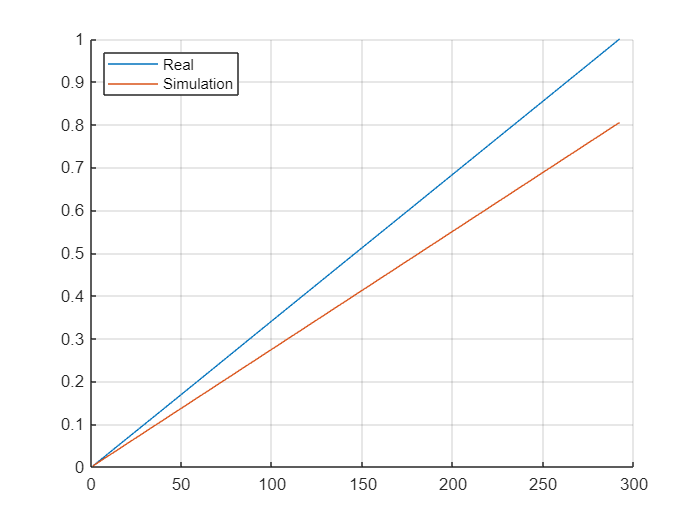

C rate: 0.10

T: 25.00

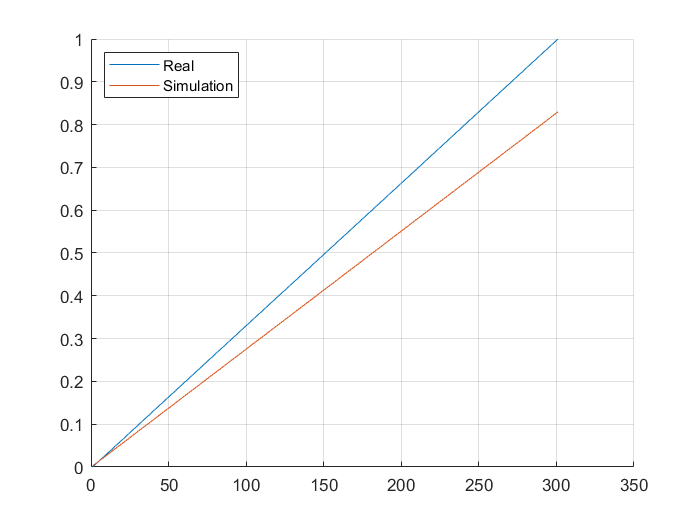

C rate: 0.10

T: 45.00

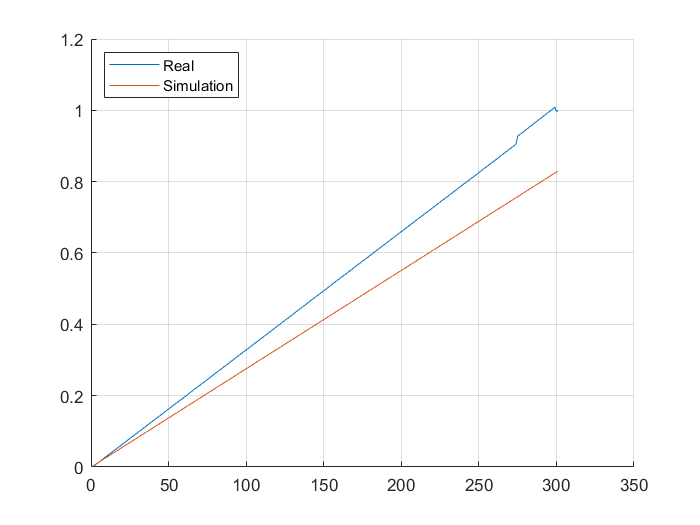

C rate: 0.20

T: 5.00

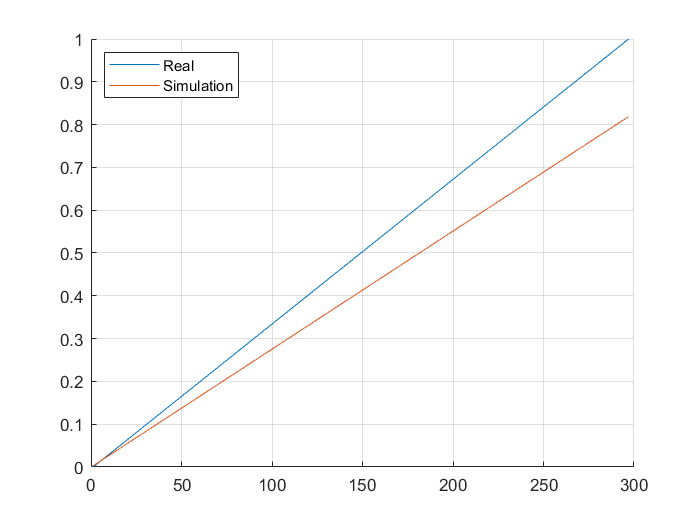

C rate: 0.20

T: 25.00

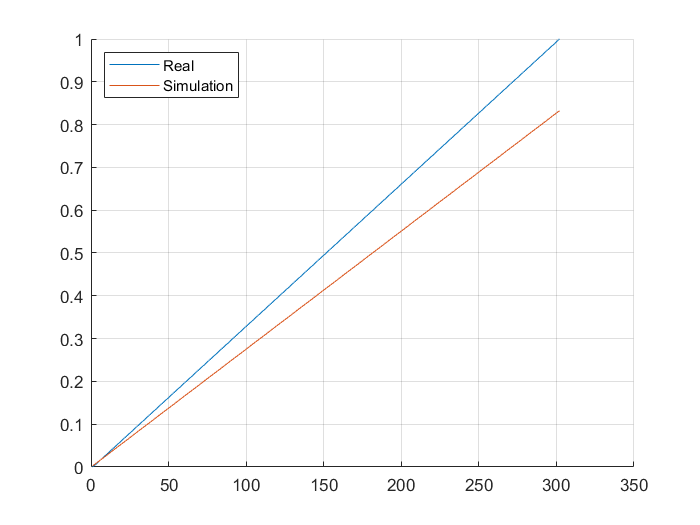

C rate: 0.20

T: 45.00

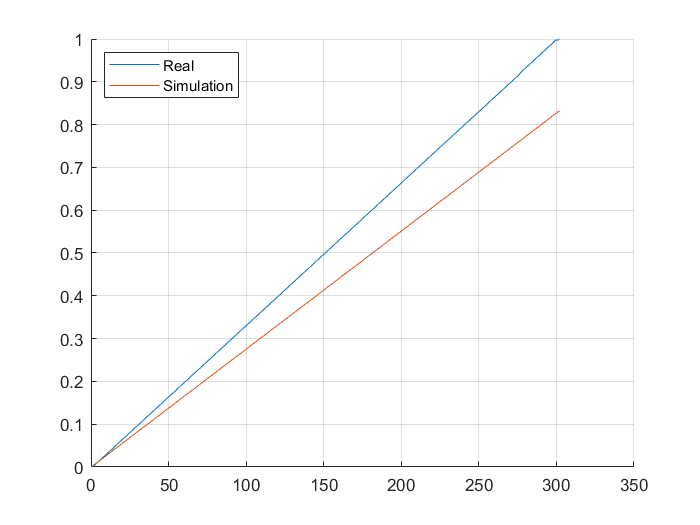

C rate: 0.50

T: 5.00

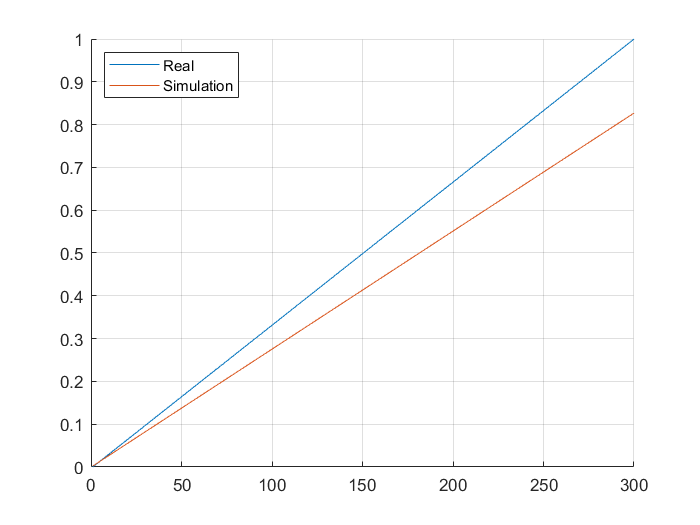

C rate: 0.50

T: 25.00

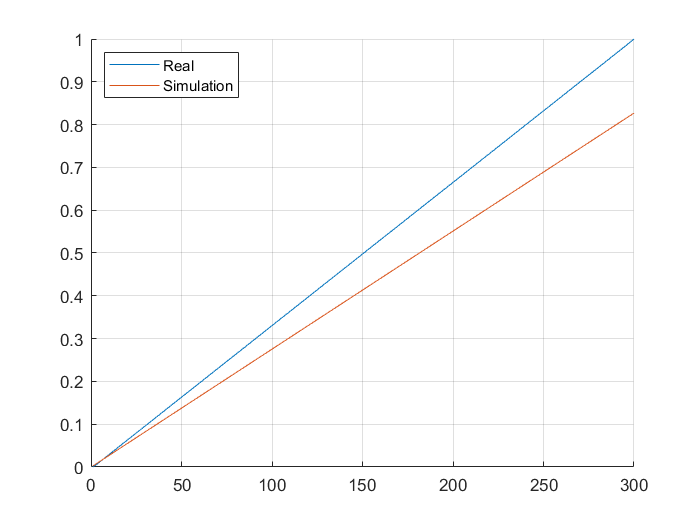

C rate: 0.50

T: 45.00

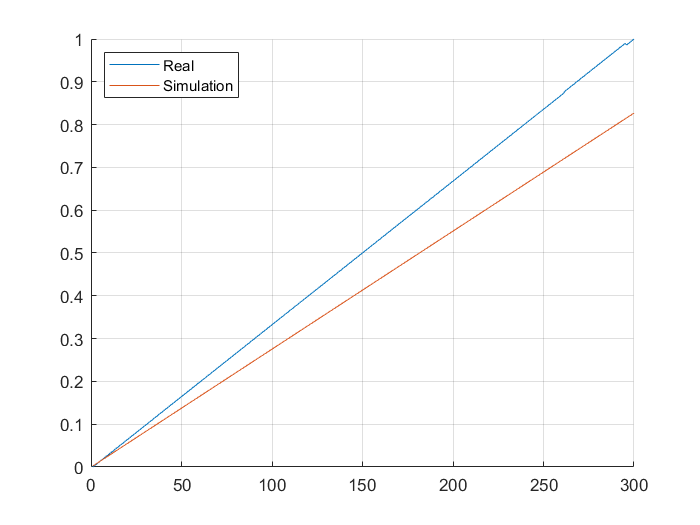

C rate: 1.00

T: 5.00

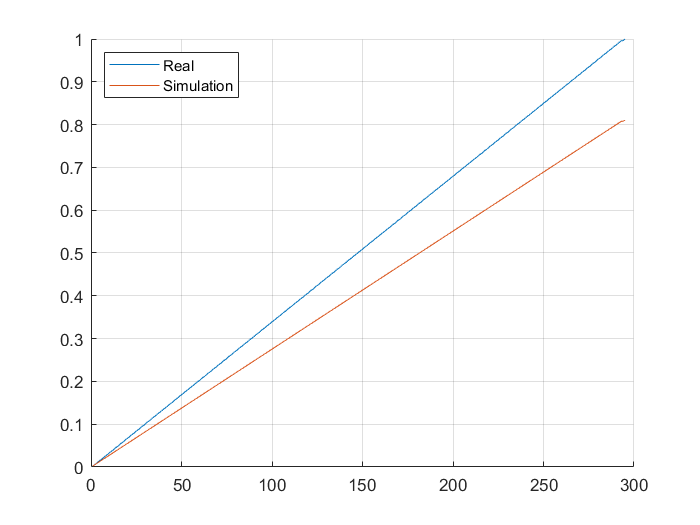

C rate: 1.00

T: 25.00

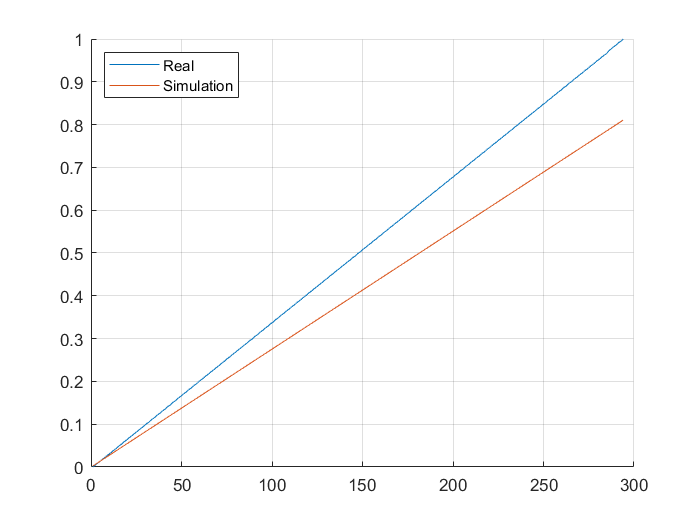

C rate: 1.00

T: 45.00

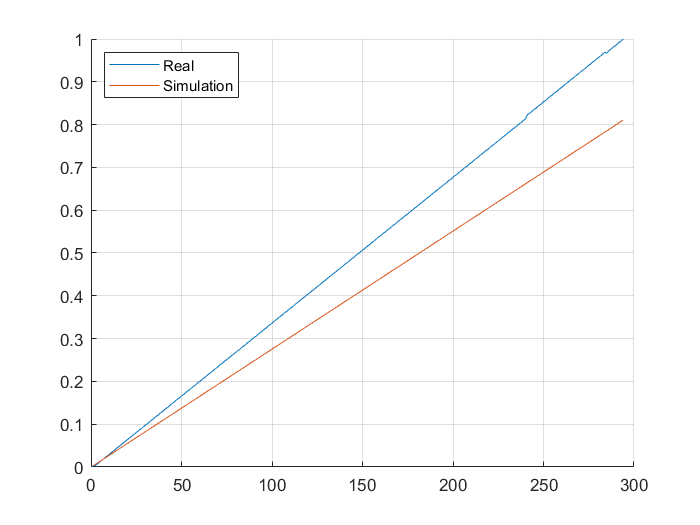

C rate: 2.00

T: 5.00

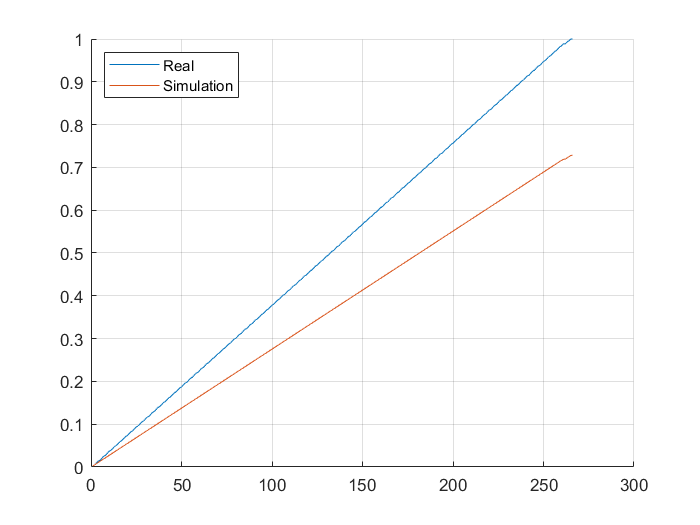

C rate: 2.00

T: 25.00

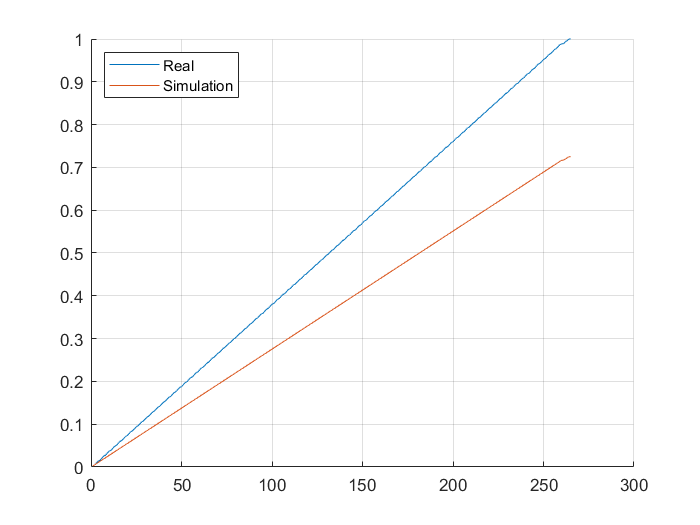

C rate: 2.00

T: 45.00

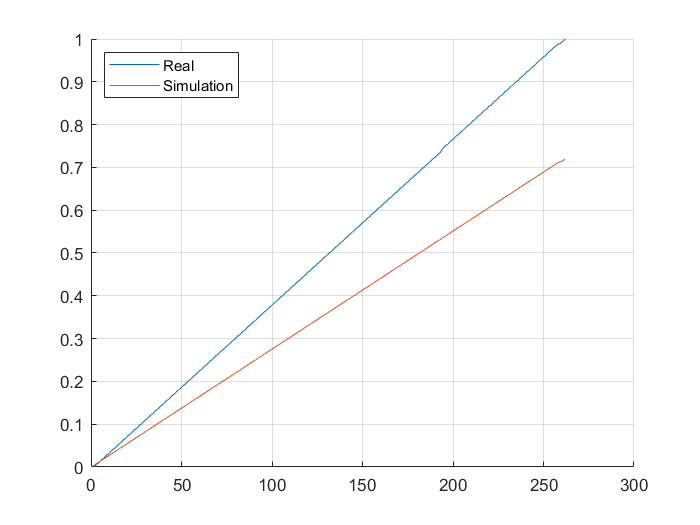

C rate: -0.10

T: 5.00

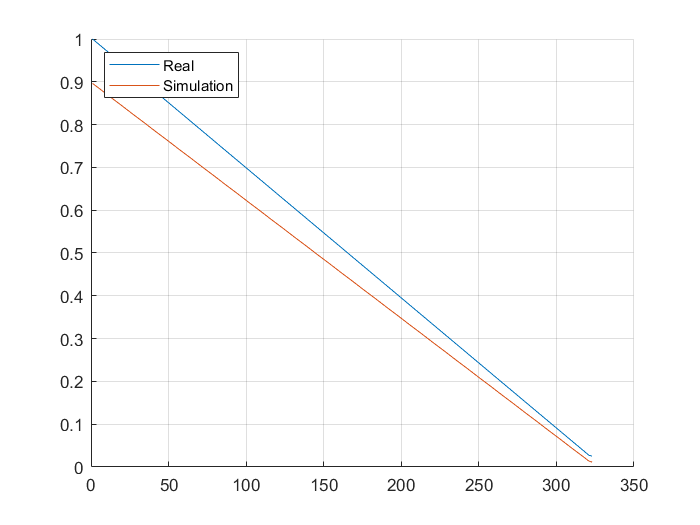

C rate: -0.10

T: 25.00

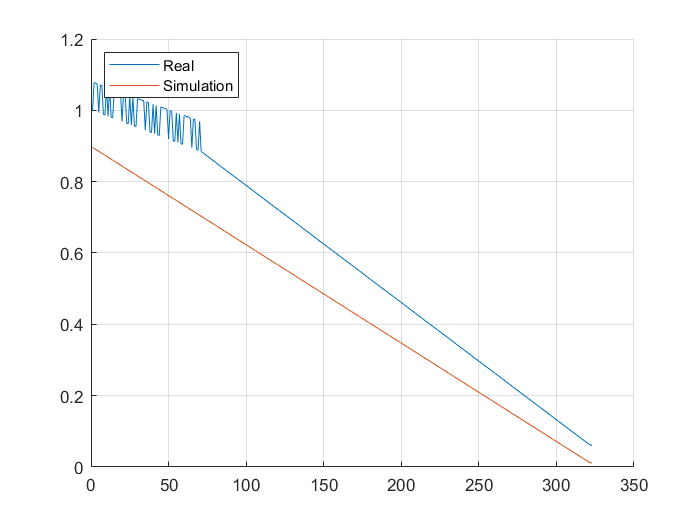

C rate: -0.10

T: 45.00

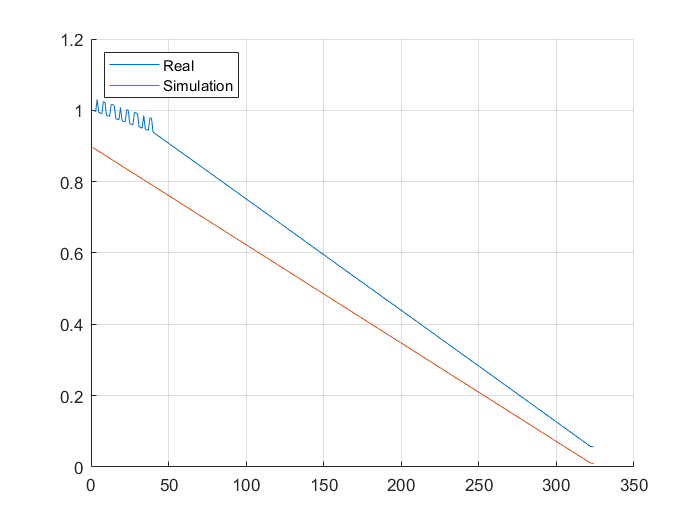

C rate: -0.20

T: 5.00

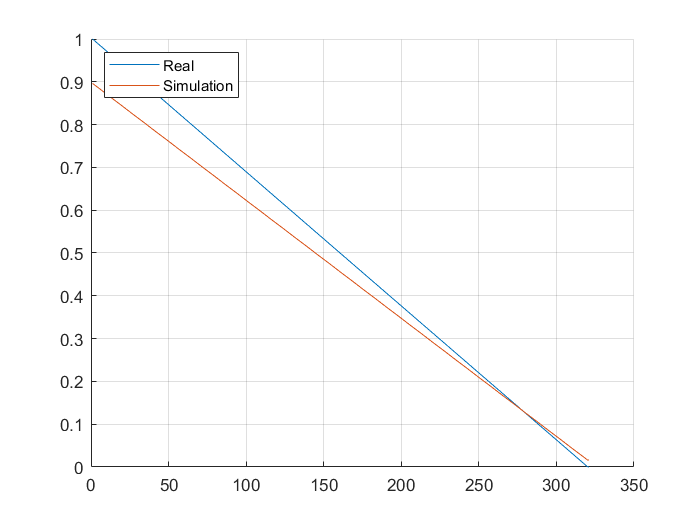

C rate: -0.20

T: 25.00

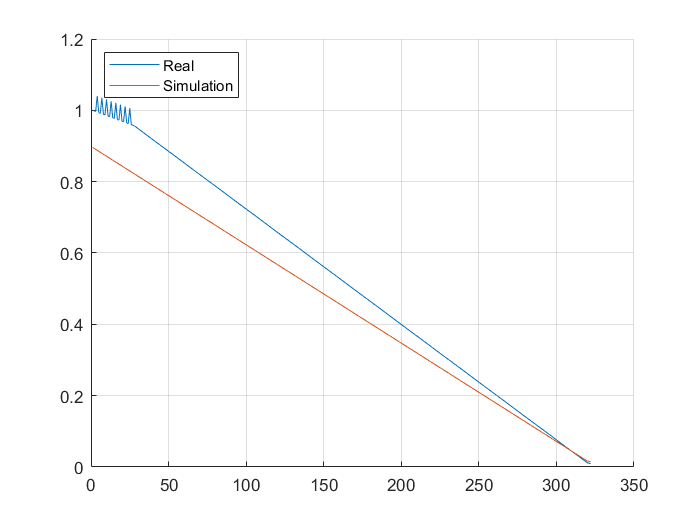

C rate: -0.20

T: 45.00

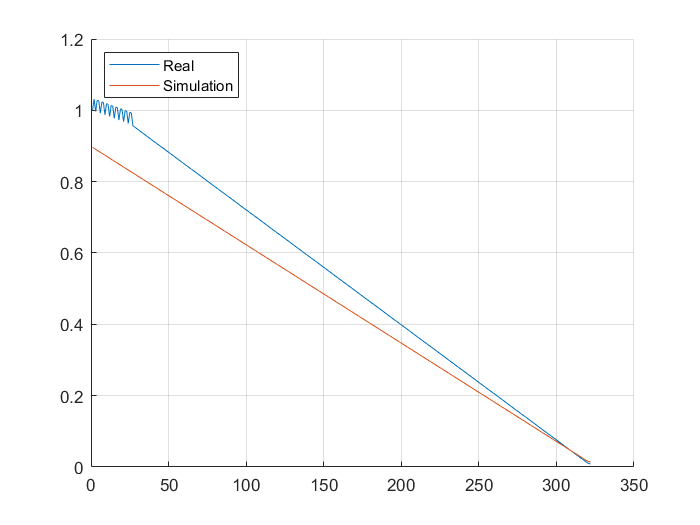

C rate: -0.50

T: 5.00

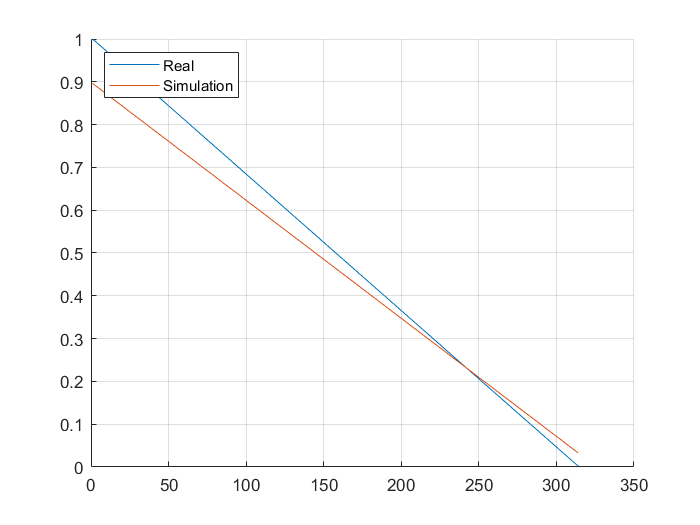

C rate: -0.50

T: 25.00

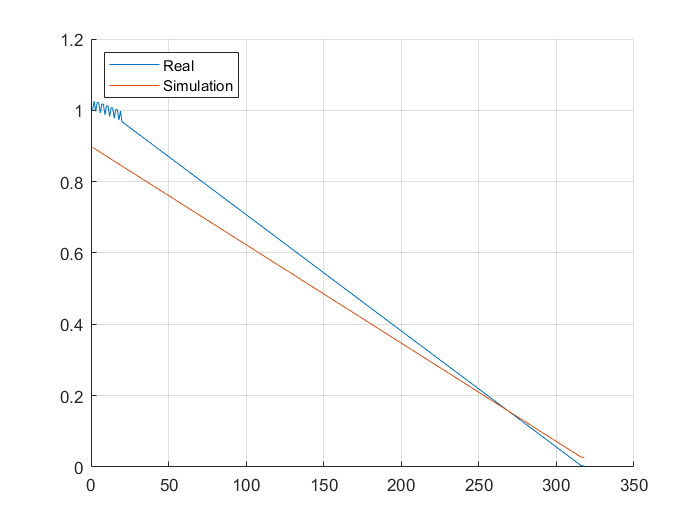

C rate: -0.50

T: 45.00

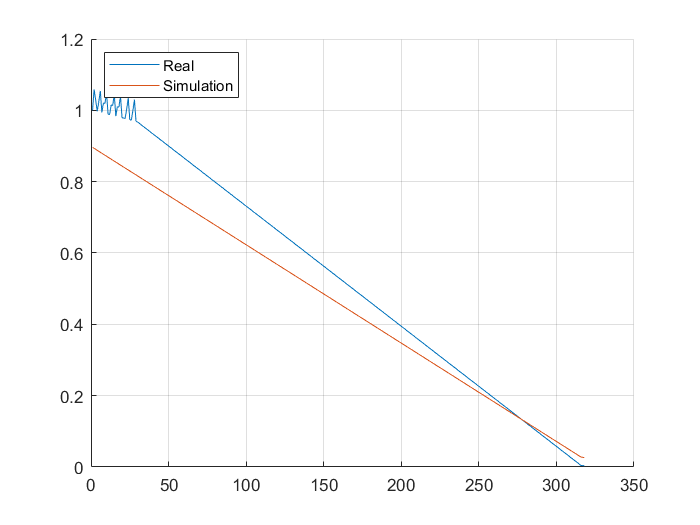

C rate: -1.00

T: 5.00

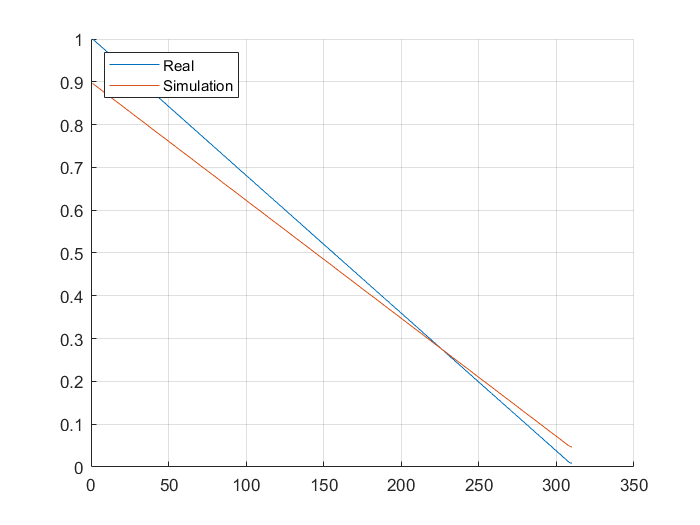

C rate: -1.00

T: 25.00

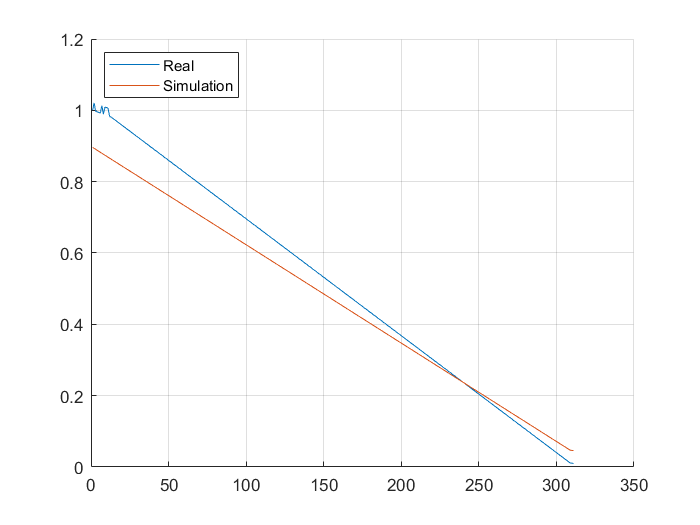

C rate: -1.00

T: 45.00

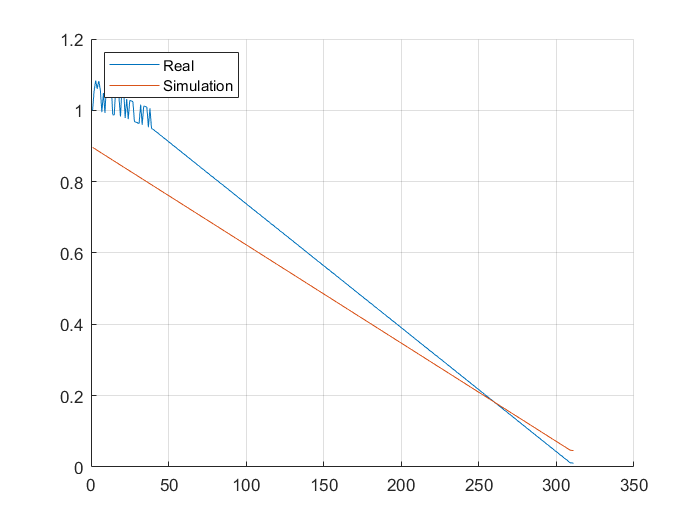

C rate: -2.00

T: 5.00

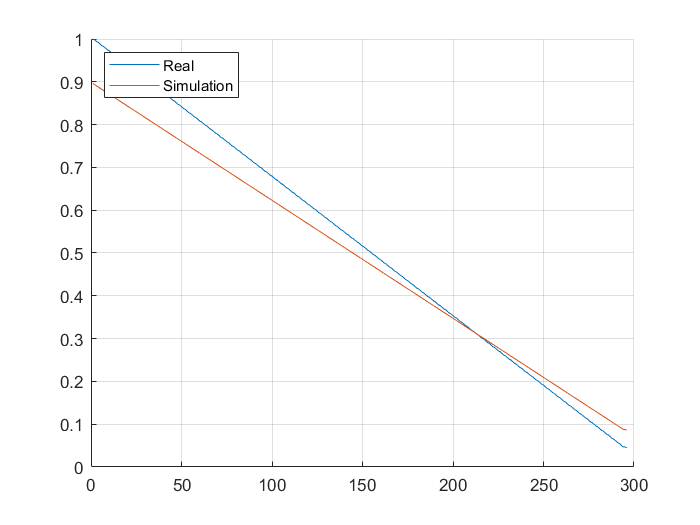

C rate: -2.00

T: 25.00

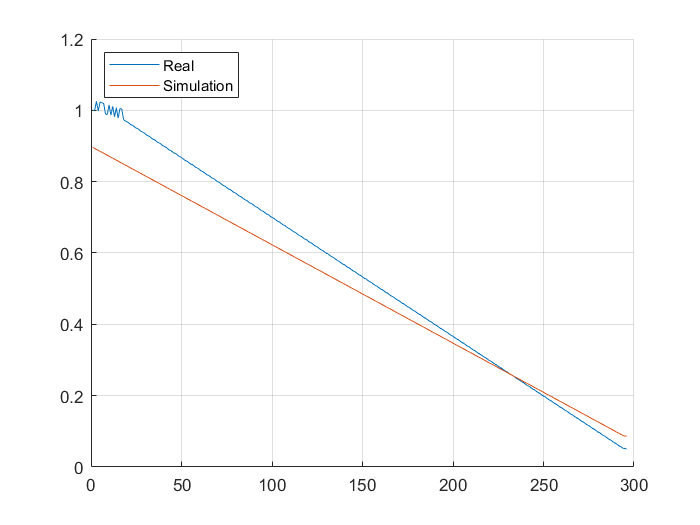

C rate: -2.00

T: 45.00

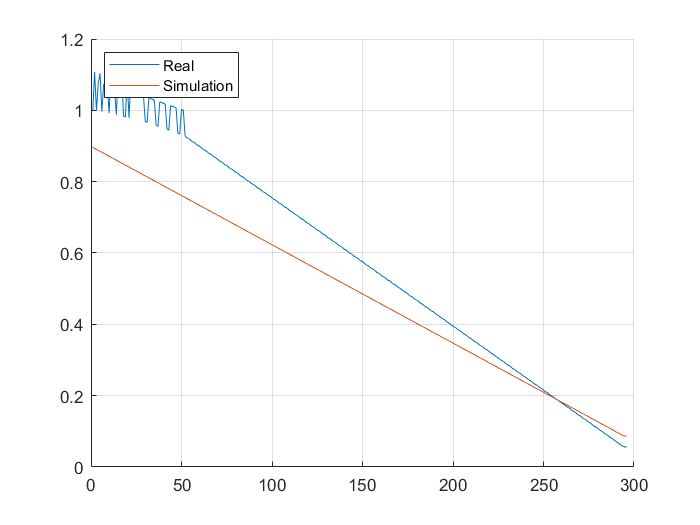

Data = [];
for c_i = 1:length(c_rates)
    for temp_i = 1:length(temps)
        tab = sim_res(sim_res.Crate == c_rates(c_i) & sim_res.T0 == temps(temp_i), :);

        target = struct2table(real(temp_i*2 - 1).test.For_sim.Crate);
        target = target(target.Crate == c_rates(c_i), :);
        [~, idx] = sort(cell2mat(target.time));

        SOC_real = cell2mat(target.capacity);
        SOC_real = SOC_real(idx);
        timestamps = floor(tab.time.d1+1);
%         fprintf("%d %d",timestamps(end), length(E_real))
        timestamps_idx = timestamps <= (length(SOC_real) + 1);
        timestamps = timestamps(timestamps_idx);

        SOC_real = SOC_real(timestamps);
        if c_rates(c_i) > 0
            SOC_real = SOC_real/SOC_real(end);
        else
%             SOC_real = (SOC_real - SOC_real(end))/SOC_real(end);
%             SOC_real = SOC_real - SOC_real(1);
            SOC_real = SOC_real/SOC_real(1);
        end
        SOC_sim = tab.SOCCell.d1;
        SOC_sim = SOC_sim(1:length(timestamps));

        fprintf("C rate: %.2f",c_rates(c_i))
        fprintf("T: %.2f",temps(temp_i) - 273.15)
        figure
        hold on
        grid on
        plot(SOC_real)
        plot(SOC_sim)
        legend(["Real", "Simulation"], "Location","northwest")
        frame = [];
        names = [];

        % Phis
        indexes = [18, 30];
        indexes = [1:18, 30:43];
        for k = 1:length(indexes)
            names = [names "phis_"+num2str(indexes(k))];
            frame = [frame tab.phis.d1(timestamps_idx, indexes(k))];
        end

        % Phil
        indexes = [1, 18, 30, 41];
        indexes = 1:41;
        for k = 1:length(indexes)
            names = [names "phil_"+num2str(indexes(k))];
            frame = [frame tab.phil.d1(timestamps_idx, indexes(k))];
        end

        % cl
        indexes = [1, 18, 30, 41];
        indexes = 1:41;
        for k = 1:length(indexes)
            names = [names "cl_"+num2str(indexes(k))];
            frame = [frame tab.cl.d1(timestamps_idx, indexes(k))];
        end

        % cs_surf
        indexes = [1, 18, 30, 43];
        indexes = [1:18, 30:43];
        for k = 1:length(indexes)
            names = [names "cs_surface_"+num2str(indexes(k))];
            frame = [frame tab.cs_surface.d1(timestamps_idx, indexes(k))];
        end

        % T
        indexes = [1, 18, 30, 41]; %#ok<*NASGU> 
        indexes = 1:41;
        for k = 1:length(indexes)
            names = [names "T_"+num2str(indexes(k))];
            frame = [frame tab.T.d1(timestamps_idx, indexes(k))];
        end
        
        % 1D variables
        vars_1D = {'Ecell' 'Epos' 'Eneg' 'capa' 'enerden' 'Qtot' 'poden'...
            'R0_estim' 'SOCneg_ave' 'SOCpos_ave' 'SOCneg_load' 'SOCpos_load' 'SOCCell' 'time' 'current'};
        for k = 1:length(vars_1D)
            cur_var = string(vars_1D(k));
            names = [names cur_var]; %#ok<*AGROW> 
            if isstruct(tab.(cur_var))
                frame = [frame tab.(cur_var).d1(timestamps_idx)];
            else
                var = cell2mat(tab.(cur_var));
                if any(isinf(var))
                    var(isinf(var)) = var(circshift(isinf(var), 1));
                end
                frame = [frame var(timestamps_idx)];
            end
        end

        names = [names, "SOC_real"];
        frame = [frame SOC_real'];

        Data = [Data; frame];
        nam_here = names;

        splits = randsample([0, 1, 2], length(timestamps), true, [0.7, 0.15, 0.15])';
        names = [names, "split"];
        frame = [frame splits];

        test = ones(length(timestamps), 1) * (temp_i*100 + c_i);
        names = [names, "test"];
        frame = [frame test];
        
%         if c_i == 1 && temp_i == 1
%             T = array2table(frame, "VariableNames",names);
%             writetable(T,'Clean_Data_Full_SOC.csv','WriteRowNames',true)
%         else
%             dlmwrite('Clean_Data_Full_SOC.csv', frame, '-append', 'precision', 14)
%         end
    end
end